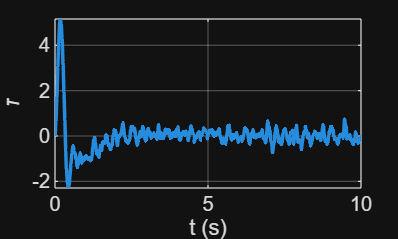

clear
close
clc

syms M_c m g l r b_v b_m J_m real
syms x(t) theta(t) x_dot theta_dot x_ddot theta_ddot
syms tau

% Differentiated variables
vars_diff = [diff(x,t,2); diff(x); x; diff(theta,t,2); diff(theta); theta];

% Inverse pendulum mass dynamics
posx_m = l*sin(theta) + x;
accx_m = diff(posx_m, t, 2); % second derivative

% Force required to accelerate the pendulums mass
F_pend = m*accx_m + b_v*diff(x, t);

% The force applied on the "cart" is
% the force generated by the motors
% minus the reaction force from the pendulum mass (x component)
F_mot = tau/r;
eq1 = (M_c + J_m/r^2)*diff(x,t,2) == F_mot - F_pend;

% Considering the load m to be a point mass at length l
eq2 = m*l^2*diff(theta,t,2) == m*g*l*sin(theta) - m*l*diff(x,t,2)*cos(theta) - tau - b_m*diff(x,t)/r;

% Collect terms
eq1 = collect(lhs(eq1) - rhs(eq1), vars_diff);
eq2 = collect(lhs(eq2) - rhs(eq2), vars_diff);

% Express symbolically
syms x theta
vars_sym = [x_ddot; x_dot; x; theta_ddot; theta_dot; theta];
eq1 = subs(eq1, vars_diff, vars_sym);
eq2 = subs(eq2, vars_diff, vars_sym);

% Nonlinear model
[M, rest] = equationsToMatrix([eq1; eq2], [x_ddot; theta_ddot]);
accels = M \ rest;

f = formula([x_dot;
             theta_dot;
             accels(1);
             accels(2)]);

% Create the model with the unknown true parameters
params = [M_c; m; g; l; r; b_v; b_m; J_m];
%values = [0.3; 0.2; 9.82; 0.05; 0.025; 0.01; 3.71*10^-5; 3.75*10^-7]; % Small balancer
values = [10; 5; 9.82; 0.4; 0.075; 0.01; 3.71*10^-5; 3.75*10^-7]; % Large balancer

model = subs(f, formula(params), values);
pendulum_dynamics = matlabFunction(model, 'Vars', {x, theta, x_dot, theta_dot, tau});

% Parameter estimation using linearized models
% Use the normal operating point but
% Create models with variation in parameters

op_state = [0; 0; 0; 0];
op_u = 0;
% m_op = [0.1; 0.2; 0.3];
% l_op = [0.05; 0.1; 0.15];
m_op = [0.5; 5; 10; 15; 20];
l_op = [0.2; 0.5; 1];

x_sym = formula([x; theta; x_dot; theta_dot]);
u_sym = tau;
p = [m; l];

A_sym = jacobian(f, x_sym);
B_sym = jacobian(f, u_sym);

A_op = subs(A_sym, [x_sym; u_sym], [op_state; op_u]);
B_op = subs(B_sym, [x_sym; u_sym], [op_state; op_u]);
C = eye(4); % 5 for augment!
Ts = 0.01;

% Augment (test)

%A_op = [A_op, B_op;
%        zeros(1,4), 1];

%B_op = [B_op; 1-eps];

% LQR weights
% -----------------

Qx = [10, 0, 0, 0;
      0, 10, 0, 0;
      0, 0, 10, 0;
      0, 0, 0, 10];

Qu = 1;

%Qu_rate = 10;

%Qx = blkdiag(Qx, Qu_rate);

% ----------------

nm = length(m_op);
nl = length(l_op);

A_grid = cell(nm, nl);
B_grid = cell(nm, nl);
K_grid = cell(nm, nl);

values_p = values;

for i = 1:length(m_op)
    for j = 1:length(l_op)

        % M_c m g l r b_v b_m J_m
        values_p(2) = m_op(i);
        values_p(4) = l_op(j);

        A_p = double(subs(A_op, formula(params), values_p));
        B_p = double(subs(B_op, formula(params), values_p));

        rank(ctrb(A_p, B_p));

        sys = ss(A_p,B_p,C,0);
        dsys = c2d(sys, Ts);
        Ad_p = dsys.A;
        Bd_p = dsys.B;

        [Kd_p, ~, ~] = dlqr(Ad_p, Bd_p, Qx, Qu);
        K_grid{i,j} = Kd_p;
        
        A_grid{i,j} = Ad_p;
        B_grid{i,j} = Bd_p;

    end
end

% Main parameters
% ---------------------------------------------

% See above
% values - "true" parameters of the system
% Qx - state weight matrix
% Qu - input weight matrix

P0 = 100*eye(4);        % Inital covariance / Ricatti solution
P_meas_prev = P0;       % Previous State error covariance
P_ctrl_prev = P0;       % Previous Ricatti solution
Q_meas = 0.01*eye(4);   % Process noise covariance
R_meas = 0.01*eye(4);   % Measurement noise covariance

x0 = [0; pi/12; 0; 0];  % Initial state for simulation

% Parameter estimation
% Temperatue (softmax)
temp = 0.01;            % < 1 means weights are chosen picky, chooses the most likely model

alpha = 0.95;           % Gain matrix LP filter weight
beta = 0.85;               % Input LP filter weight
K_prev = zeros(1,4);

H = C;  % Measurement model

% Assume zero mean measurement noise
sigma_x = 0.01;         % 1cm
sigma_th = 0.02;        % ~1 deg
sigma_x_dot = 0.01;     % 1 cm/s
sigma_th_dot = 0.02;    % ~1 deg/s^2
sigma = [sigma_x; sigma_th; sigma_x_dot; sigma_th_dot];

% ---------------------------------------------

t_end = 10;
T = 0:Ts:t_end;

x_filtered = zeros(4,1);
u_prev = 0;

t_traj = [];
t_meas = [];
x = x0;
X = [];
X_filtered = [];
P_filtered = [];
Y = [];
U = [];
% Iters = 0;  % For Ricatti solution within tol or maxiter

% Simulate the system with nonlinear dynamics and sample it as the
% "real" system. Estimate parameters with the gainGridEstimator method
% And calculate a new filtered controller gain (LP filter)
% Filter the measurement with the blended model
% Apply control signal

for k = 1:length(T)-1

    % Compute noise, use in linear and nonlinear model
    noise = normrnd(0, sigma);

    % Nonlinear simulator
    % Integrate nonlinear system over [T(k), T(k+1)] with constant u
    ode = @(t,x) pendulum_dynamics(x(1), x(2), x(3), x(4), u_prev);
    [tk, xk] = ode45(ode, [T(k), T(k+1)], x); % Simulate from "true" state
    x = xk(end,:).';
    y = x + noise;
    
    % Estimate matricies and gain
    [K_blend, A_blend, B_blend] = gainGridEstimate(y, H, R_meas, x_filtered, P_meas_prev, A_grid, Q_meas, B_grid, u_prev, K_grid, temp);
    K_filtered = alpha*K_prev + (1-alpha)*K_blend;
    K_prev = K_filtered;

    [x_filtered, P_meas] = kalmanFilter(y, H, R_meas, x_filtered, P_meas_prev, A_blend, Q_meas, B_blend, u_prev);

    u = - (1-beta)*K_filtered*x_filtered + beta*u_prev;
    
    P_meas_prev = P_meas; % Normal kalleman filter
    u_prev = u;
    z_prev = [x; u];

    % Append trajectory
    t_traj = [t_traj; tk];
    X = [X; xk];
    
    % Store states
    t_meas = [t_meas; tk(1)];
    Y = [Y; y.'];
    U = [U; u*ones(length(tk),1)];
    X_filtered = [X_filtered; x_filtered.'];
end

figure(2)
plot(t_traj, U, 'LineWidth', 1.5);
xlabel('t (s)');
ylabel('\tau');
grid on;

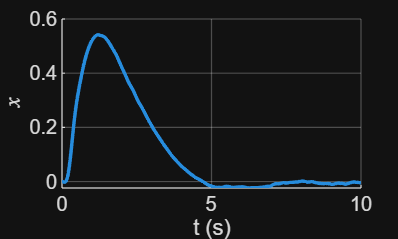

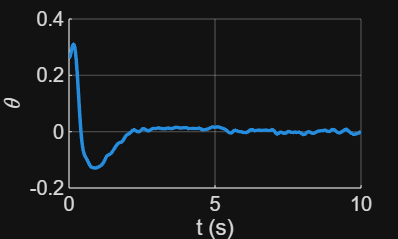

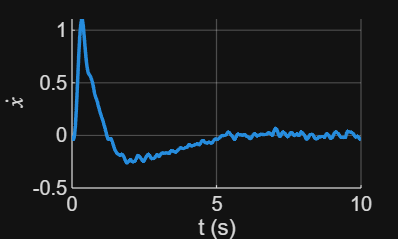

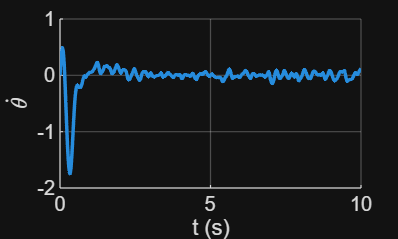


% Plots
states = ["$x$"; "$\theta$"; "$\dot{x}$"; "$\dot{\theta}$"];
for i = 1:size(X,2)
    figure;
    hold on
    plot(t_traj, X(:,i), 'LineWidth', 1.5);
    % scatter(t_meas, Y(:,i), 5, 'filled');
    % plot(t_meas, X_filtered(:,i), 'LineWidth',1.5);

    xlabel('t (s)');
    ylabel(states(i),'Interpreter','latex');
    grid on;
    hold off
end


% figure(3)
% plot(T, Iters, 'LineWidth', 1.5);
% xlabel('t (s)');
% ylabel('k');
% grid on;

% Conclusion:
% It is desirable to have the ability to adapt to changing parameters of
% the pendulum. This algorithm both estimates parameters without having to
% measure them directly and applies an approximated stabilizing controller.
% The function gainGridEstimate uses a log-likelihood calculation on the
% current filtered measurement and compares this to the prediction given by
% the pre-generated grid matricies. Temperature is used to smoothly filter between
% the different models. A lower temp means that weights will be more biased to the
% most likely models, which means they have greater contribution to the resulting
% system matricies A_blend, B_blend and the new gain K_blend.
% A_blend and B_blend are also used to filter the state estimates to
% complement K_blend in the iteration.

% A function getdLQR was also tested, but the resulting K_blend was not
% much better than the (comparatively inexact) K_blend. getdLQR requires solving
% the discrete time Ricatti equation every time step. This depends on
% previous solutions P_prev and requires setting limits for the iteration
% manually (tol and maxiter) which sets limits on how good the solution is.

% Since predicting, calculating likelihoods and blending takes almost a
% fixed amount of time it is suitable to use online, and the size of the
% parameter space can be changed to reduce the amount of computation or
% increase accuracy in the estimation.

% The largest source of error in this simulation is the effect of unknown
% parameters and the exact values for friction and inertias of the robot.
% It is also assumed that the torque output from the motor is also
% immediate and is applied exactly as requested by the controller.
